# Rad229_EPI_Ghosting demonstrates ghosting artifacts in EPI.

% These questions can be used to further explore the code and concepts.

%     1) Examine a range of sys.dB0_ppm to explain why ghosting artifacts in EPI remain challenging to eliminate.

%     2) Why are EPI ghosting artifacts less of a problem at lower B0?

%     3) What is the impact of shorter echo spacing on EPI ghosting?

%     4) The EPI ghosting artifacts for constant B0-field shifts always show a ghost at FOV/2. Why?

%     5) [Advanced] Compare the EPI ghosting artifacts between constant and linear field shifts. Explain the orgins of the 

%     differences (this is not obvious!). See Bernstein Chp. 16.1.

% DBE@STANFORD.EDU (May 2021) for Rad229

## Define MRI system, acquisition, abd object constants

sys = Rad229_MRI_sys_config;  % Load standard system parameters

acq.Nx = 128;  % Matrix is NxM (then padded later to accomodate motion)
acq.ESP = 1000e-6;  % Echo spacing [s]

## Define the off-resonance field

sys.dB0_ppm = 3.5e-6; % sys.B0 shift [ppm]
sys.dB0 = sys.dB0_ppm * sys.B0;  % sys.B0 shift [T]
sys.f0 = sys.gamma_bar * sys.dB0;  % Frequency offset [Hz]
% Note - For this example we assume an MRI system-level off-resonance (not object specific)

## Create Phantom Object

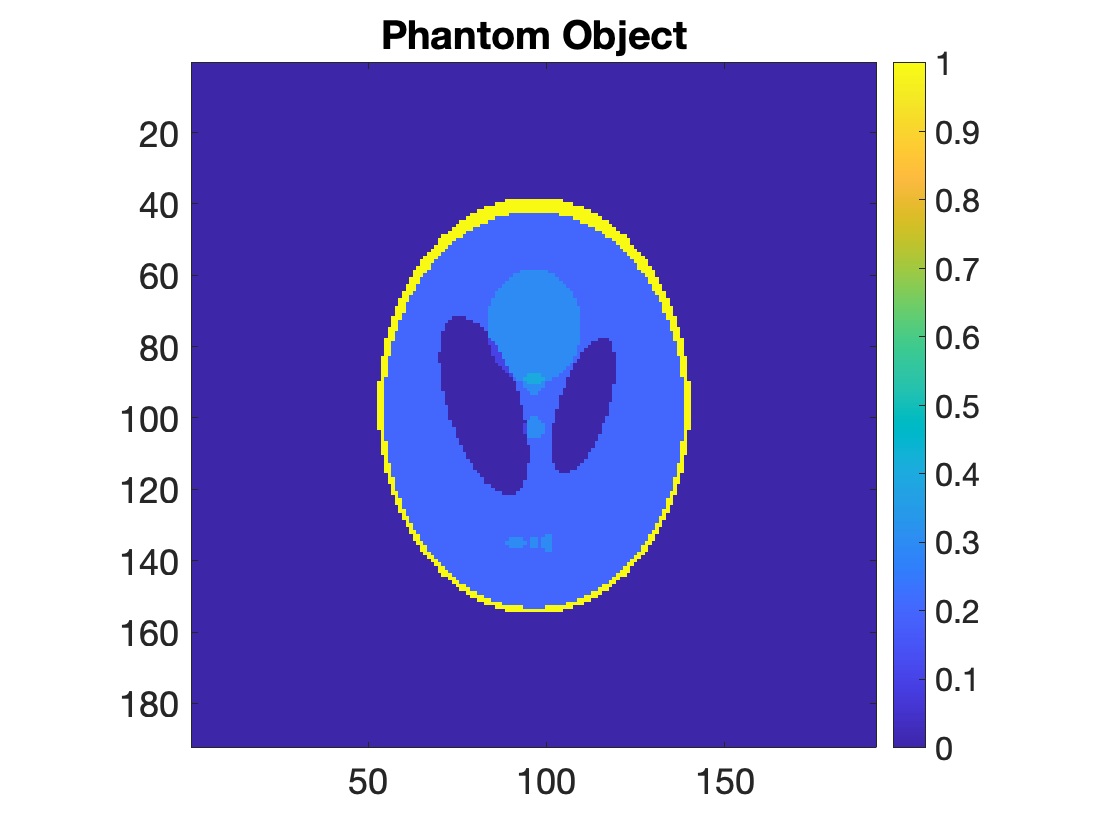

[ P , M ] = Rad229_MRI_Phantom( acq );
P = padarray( P , [ acq.Nx / 4 acq.Nx / 4] , 0 , 'both' ); % Just helps see aliasing...

acq.Nx = size( P , 1 );  % Update matrix size after padding

figure; imagesc( abs(P) ); axis equal tight; title('Phantom Object'); 
  colorbar; caxis([0 1]);

## Generate a spatially independent and CONSTANT phase shift

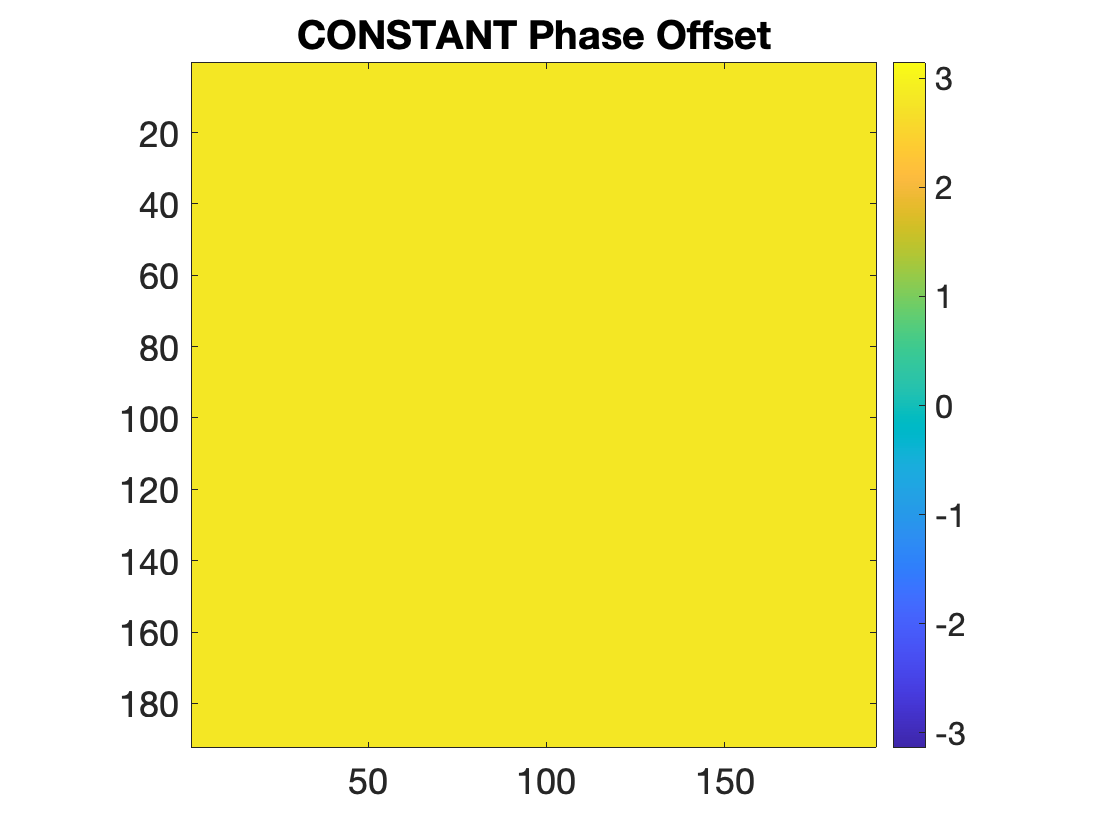

% Generate a spatially independent and constant phase that arises from a 
% constant B0-field offset (sys.B0). This could arise from B0 eddy currents
% or frequency mistmatches for off-center imaging. 
% ==> See Berntein Section 16.1 (page 727) for more information.

sys.dphs = 2 * pi * sys.f0 * acq.ESP;  % Phase offset [rad]

sys.phs = sys.dphs .* ones( size( P ) ); % Phase offset field [rad]

figure; imagesc( sys.phs ); axis equal tight; title('CONSTANT Phase Offset'); 
  colorbar; caxis([-pi pi]);

## EPI Nyquist ghosting (CONSTANT phase shift)

% Even echoes "see" the +phs; odd echoes "see" the -phs
obj.P_odd = P .* exp( +1i * sys.phs );
obj.P_even = P .* exp( -1i * sys.phs );

% EPI readout mixes even and odd echoes...
kspc.odd = fftshift( fft2( obj.P_odd ) );   % Define the odd-line k-space
kspc.even = fftshift( fft2( obj.P_even ) ); % Define the even-line k-space

% Define the acquired k-space (interleaved odd and even lines)
kspc.P = zeros( size( kspc.even ) );
kspc.P( 1 : 2 : end , : ) = kspc.odd( 1 : 2 : end , : );
kspc.P( 2 : 2 : end , : ) = kspc.even( 2 : 2 : end , : );

% Reconstruct and image of object and add some noise
IM = ifft2( fftshift( kspc.P ) ); 
IM = IM + ( randn( size(IM) ) + 1i * randn( size(IM) ) ) / 25; % Add some complex noise

## Create a Figure

disp('Note the GHOSTING!');

Note the GHOSTING!


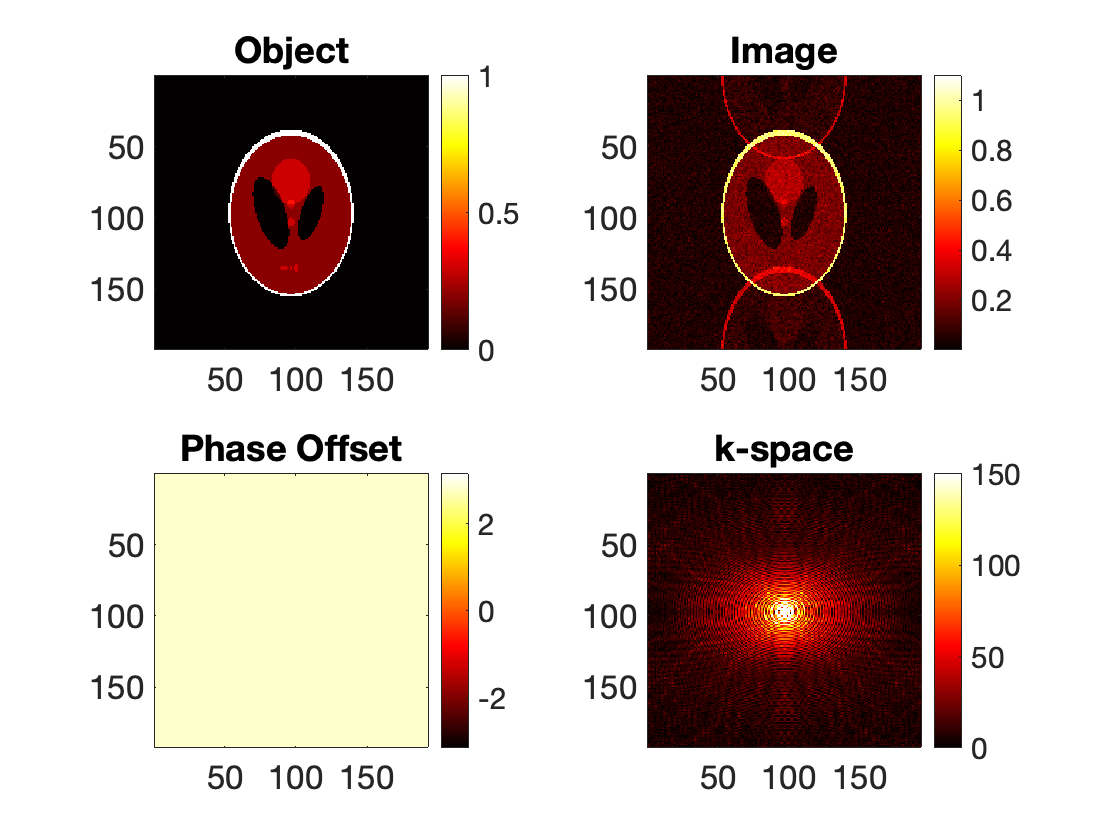

figure; hold on; colormap(hot);
  subplot(2,2,1); imagesc(abs(P));  title('Object');  colorbar; axis equal tight;
  subplot(2,2,2); imagesc(abs(IM));  title('Image');   colorbar; axis equal tight;
  subplot(2,2,3); imagesc(sys.phs);  title('Phase Offset');   colorbar; axis equal tight; caxis([-pi pi]);
  subplot(2,2,4); imagesc(abs(kspc.P));  title('k-space'); colorbar; axis equal tight; caxis([0 150]);

## Generate a spatially independent and LINEAR phase shift

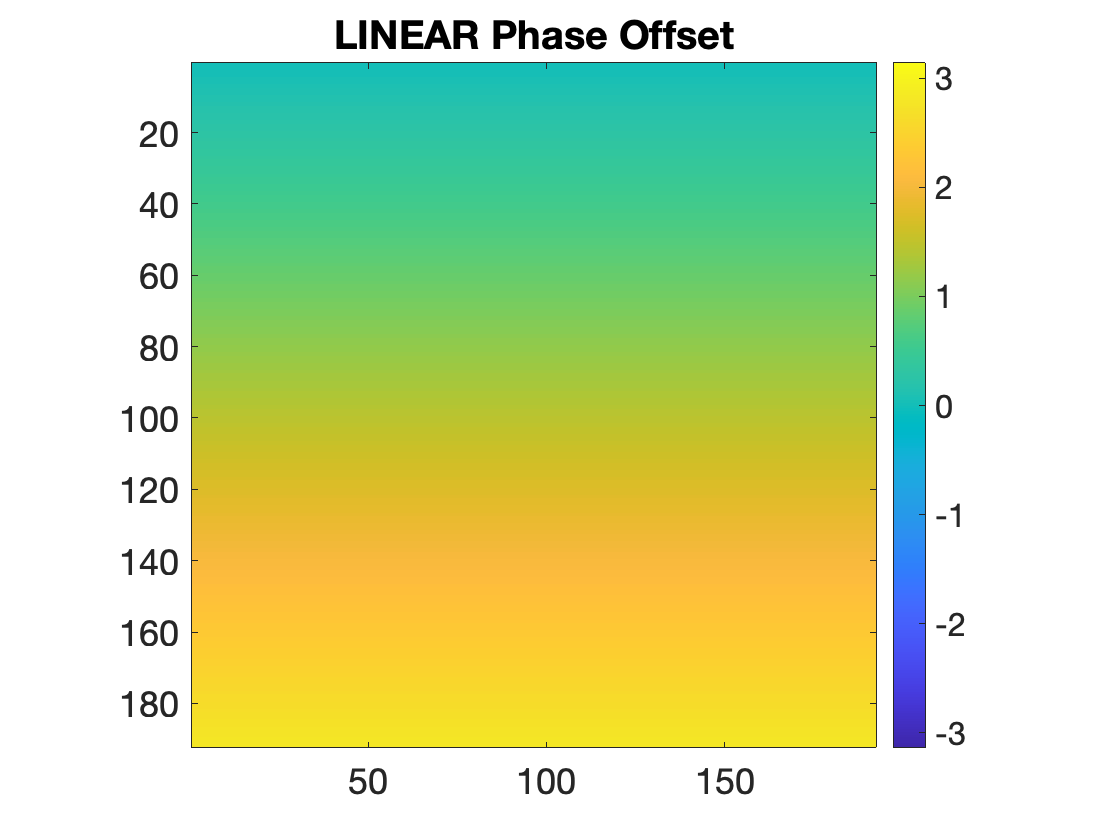

% Calculate a linear phase that arises from a linear B0-field shift (sys.B0)
% A linear B0-field shift may arise from linear edy currents, gradient
% delays, or gradient hysteresis.
% ==> See Berntein Section 16.1 (page 728) for more information.

sys.dphs = 2 * pi * sys.f0 * acq.ESP;  % Phase offset [rad]
sys.phs = sys.dphs * repmat( linspace( 0 , 1 , acq.Nx )' , [1 acq.Nx]); % Constant phase offset [rad]

figure; imagesc( sys.phs ); axis equal tight; title('LINEAR Phase Offset'); 
  colorbar; caxis([-pi pi]);

## EPI Nyquist ghosting (LINEAR phase shift)

% Even echoes "see" the +phs; odd echoes "see" the -phs
obj.P_odd = P .* exp( +1i * sys.phs );
obj.P_even = P .* exp( -1i * sys.phs );

% EPI readout mixes even and odd echoes...
kspc.odd = fftshift( fft2( obj.P_odd ) );   % Define the k-space
kspc.even = fftshift( fft2( obj.P_even ) ); % Define the k-space

kspc.P = zeros( size( kspc.even ) );
kspc.P( 2 : 2 : end , : ) = kspc.even( 2 : 2 : end , : );
kspc.P( 1 : 2 : end , : ) = kspc.odd( 1 : 2 : end , : );

IM = ifft2( fftshift( kspc.P ) ); % Image of object

## Create a Figure

disp('Note both the GHOSTING and SIGNAL loss.');

Note both the GHOSTING and SIGNAL loss.


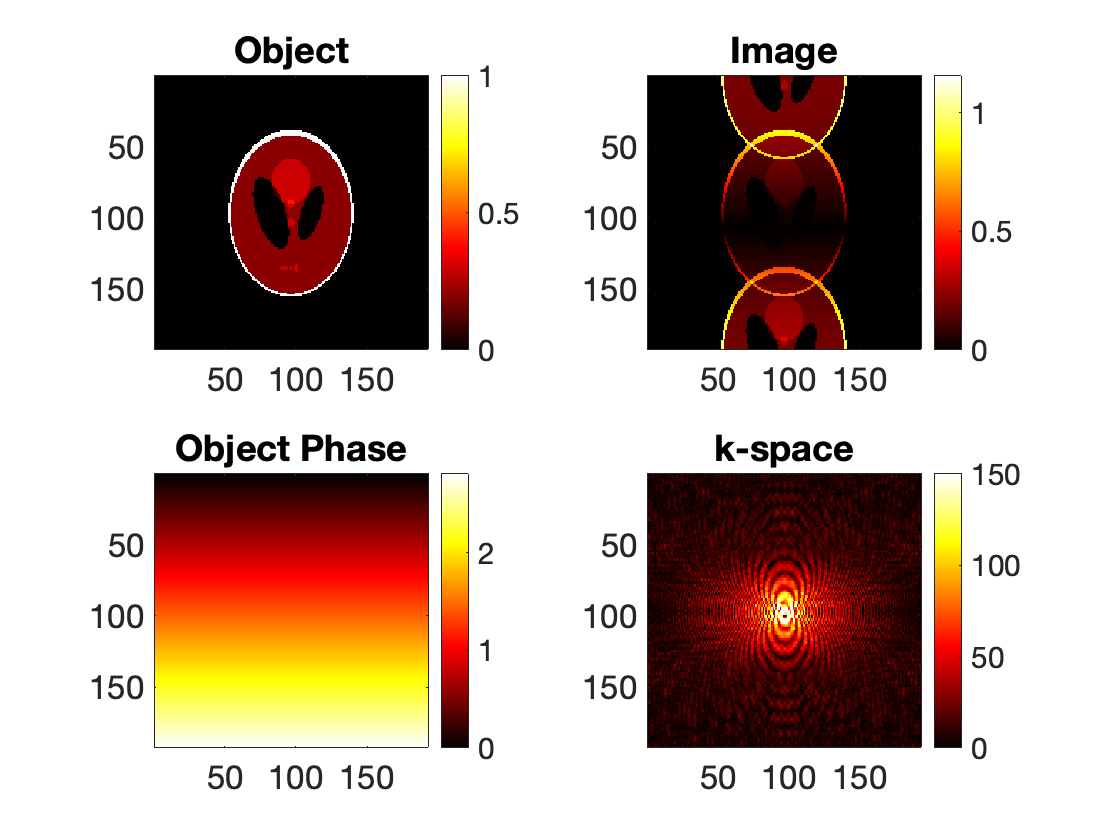

figure; hold on; colormap(hot);
  subplot(2,2,1); imagesc(abs(P));  title('Object');  colorbar; axis equal tight;
  subplot(2,2,2); imagesc(abs(IM));    title('Image');   colorbar; axis equal tight;
  subplot(2,2,3); imagesc(sys.phs);    title('Object Phase');   colorbar; axis equal tight;
  subplot(2,2,4); imagesc(abs(kspc.P)); title('k-space'); colorbar; axis equal tight; caxis([0 150]);